clear;
open_system('task_1_simm');
set_param('task_1_simm/x', 'VariableName', 'x')
set_param('task_1_simm/u', 'VariableName', 'u')

A = [5 8 5; -6 -9 -8; 6 6 5];
B = [2; 0; 0];
x0 = [1; 1; 1];

K1 = [-5.0390 -4.6284 -4.4944];
K2 = [-7.9405 -5.9449 -8.1697];
K3 = [-4.1539 -4.0983 -3.4959];
K4 = [-5.0390 -4.6284 -4.4944];

J1 = 21.7837;
J2 = 42.7327;
J3 = 174.5511;
J4 = 217.8366;
K = K1;
alpha = 10;
Q = eye(3);
R = 1;


out = sim('task_1_simm');

xx =  out.u.Data;
disp(xx(2, :, 1));

  -14.1536



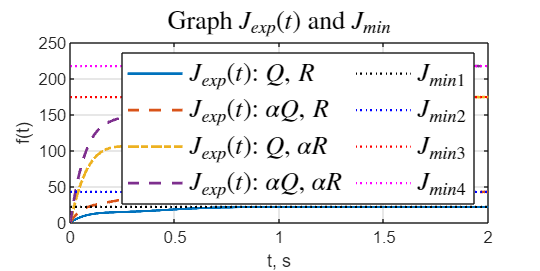




figure('Position', [100 100 800 400])
J_1 = J_sc(out.x.Time, out.x.Data, out.u.Data, Q, R);

plot(out.x.Time, J_1,'-', 'LineWidth',1.5);
hold on
K = K2;
out = sim('task_1_simm');
J_2 = J_sc(out.x.Time, out.x.Data, out.u.Data, alpha*Q, R);
plot(out.x.Time, J_2,'--', 'LineWidth',1.5);
K = K3;
out = sim('task_1_simm');
J_3 = J_sc(out.x.Time, out.x.Data, out.u.Data, Q, alpha*R);
plot(out.x.Time, J_3,'-.', 'LineWidth',1.5);
K = K4;
out = sim('task_1_simm');
J_4 = J_sc(out.x.Time, out.x.Data, out.u.Data, alpha*Q, alpha*R);
plot(out.x.Time, J_4,'--', 'LineWidth',1.5);

plot(out.x.Time, J1 * sign(out.x.Time + 1),'k:', 'LineWidth',1.25);
plot(out.x.Time, J2 * sign(out.x.Time + 1),'b:', 'LineWidth',1.25);
plot(out.x.Time, J3 * sign(out.x.Time + 1),'r:', 'LineWidth',1.25);
plot(out.x.Time, J4 * sign(out.x.Time + 1),'m:', 'LineWidth',1.25);

grid()
title('Graph $J_{exp}(t)$ and $J_{min}$','Interpreter','latex',  'FontSize', 14)
legend('$J_{exp}(t)$: $Q$, $R$', '$J_{exp}(t)$: $\alpha Q$, $R$', ...
    '$J_{exp}(t)$: $Q$, $\alpha R$', '$J_{exp}(t)$: $\alpha Q$, $\alpha R$', ...
    '$J_{min1}$', '$J_{min2}$', ...
    '$J_{min3}$', '$J_{min4}$','Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off




%{
figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5);
grid()
title('Graph $x(t)$ for $\alpha Q$, $\alpha R$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off
%}
%{
figure('Position', [100 100 800 400])
plot(out.u,'-', 'LineWidth',1.5);
hold on
K = K2;
out = sim('task_1_simm');
plot(out.u,'--', 'LineWidth',1.5);
K = K3;
out = sim('task_1_simm');
plot(out.u,'-.', 'LineWidth',1.5);
K = K4;
out = sim('task_1_simm');
plot(out.u,'k:', 'LineWidth',1.5);
grid()
title('Graph $u(t)$','Interpreter','latex',  'FontSize', 14)
legend('$u(t)$: $Q$, $R$', '$u(t)$: $\alpha Q$, $R$', '$u(t)$: $Q$, $\alpha R$', '$u(t)$: $\alpha Q$, $\alpha R$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off
%}


function [J] = J_sc(time, x, u, Q, R)
    for i = 1:length(x)
        data(i) = x(i, :, 1) * Q * x(i, :, 1)' + u(i, :, 1)'*R *u(i, :, 1);
        J(i) = trapz(time(1:i), data(1:i)', 1);
    end
end